# ELEC-8103 – Modelling, Estimation, and Dynamic Systems

# Assignment 2

# Deadline: **1.10.2023 at 23:59**

# **2. Problem 1 (5 points)**

#### **Read carefully the document “CruiseControlSystem.pdf” available in the “Assignment 2” section of MyCourses.**

#### **This document describes a cruise control system where the throttle input is denoted by **$u$** and the car speed output is denoted by **$v$.

#### **a) Construct the cruise control system (Equation 3.3 in the pdf document) in Simulink. Save the model as “problem1Simulink.mdl”. (2.5 points)  **

#### **b) Simulate the system in Simulink using a gear ratio of **$\alpha_3$** and a throttle input of **$u=$0.7. (1 point). 

- **Use the system parameter values specifed below (they are copied from the pdf document).**

- **What is the steady-state value of car's speed (**$v$**), assuming that the road surface is flat (**$\theta =0$**)?**

- **Insert the plot of simulated car's speed (**$v$**) below.**

**Hint****: **

- **Steady-state value is the output value as time approaches infinity. So, simply run your simulation for a sufficiently long time.**

- **To insert the plot, you can simply take a snapshot of the plot in the Scope block and click INSERT**→**IMAGE in the top toolbar.**

clear

u = 0.7 ; % Input (rate of fuel injection)

% System parameters:
an = 16; % Gear ratio (it can be selected from [40, 25, 16, 12, 10])
m = 800; % (kg) Mass of the car
Tm = 190; % (N*m) Maximum engine torque 
wm = 420; % (rad/s) Maximum engine speed
beta = 0.4; % Combustion coefficient
g = 9.8; % (m/s^2) Gravitational acceleration
Cr = 0.01; % Rolling friction coefficient
rho = 1.3; % (kg/m^3) Air density
Cd = 0.32; % Drag coefficient
theta = 5; % (deg) Road slope
A = 2.4; % (m^2) Frontal area of the car

%---------------------------------------------------------------
%             the steady-state value of car's speed is 50.95
%---------------------------------------------------------------

# 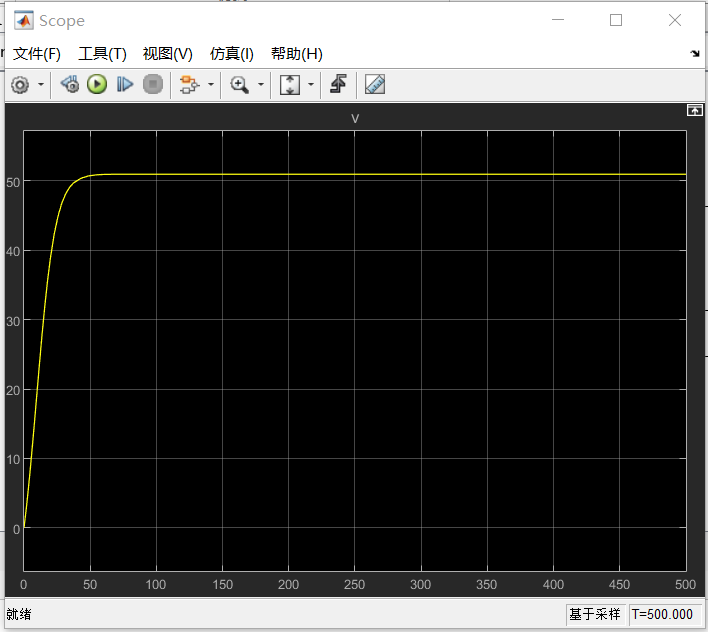

#### **c) Using the Simulink model, answer the following questions:**

- **What is the steady-state value of the vehicle's speed if the road has a 5-degree slope (**$\theta =5$**)? Insert the corresponding plot of simulated car's speed (**$v$**) below.**

- **What should the throttle input value (**$u$**) and gear ratio (**$\alpha_{\mathit{\mathbf{n}}}$**) be to maintain the same steady-state speed (**$v$**) as when driving on a flat surface, i.e., when **$\theta =0$**?**

# 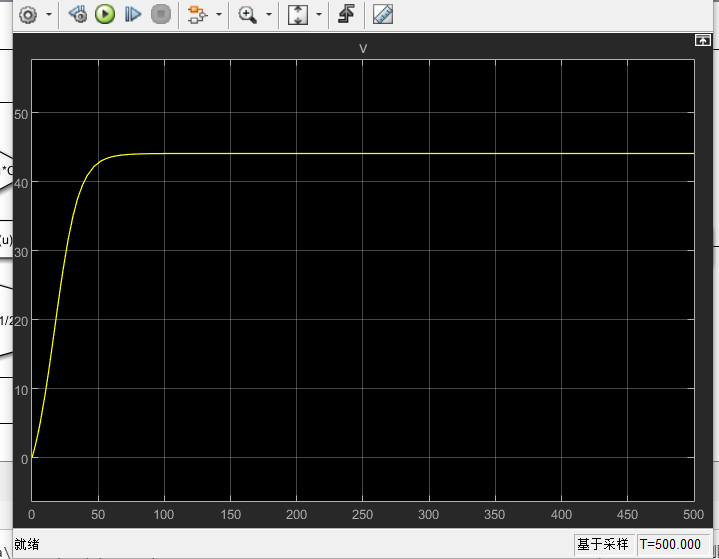

%---------------------------------------------------------------
%                       Your Answer Below
%    if theta is 5 the steady-state value of car's speed is 44.12
%    u is 1.0 and an should be 12 can make it same as driving on the flat surface
%--------------------------------------------------------------

# **2. Problem 2 (5 points)**

**Consider the system of two coupled water tanks shown in Fig. 1 below.**

- **The volumetric inflow to the upper tank is denoted by **$q_1^{\textrm{in}}$** (**${\mathrm{m}}^3$**/**s**).**

- **The inflow is generated by an input voltage **$V$** applied to a pump with a constant **$K$**. In other words, **$q_1^{\textrm{in}} \left(t\right)=V\left(t\right)\cdot K$**.**

- **Water flows from the upper tank to the lower tank through an orifice located at the bottom of the upper tank. The lower tank's outflow is then emptied into a liquid basin. **

- **The cross-sectional areas of the upper and the lower tanks are denoted by **$A_1$** and **$A_{2\;}$**.**

- **The areas of the orifices of the upper and the lower tanks are denoted by **$a_1$** and **$a_{2\;}$**.**

- **We are interested in the water levels in the tanks, which are denoted by **$h_1$** and **$h_2$**.**

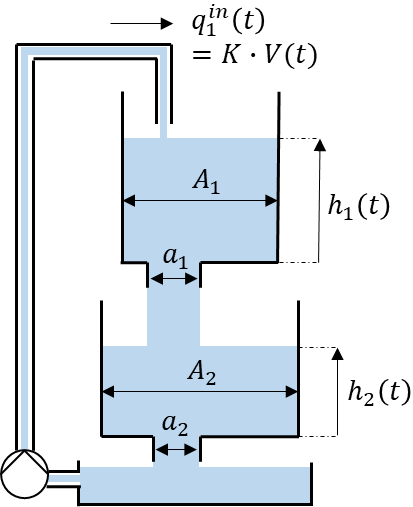

**Figure 1** – Two-tank system.

#### **a) Answer the following **questions**: (0.5 points) **

- **What signal(s) are the output(s) of the system?**

- **What signal(s) are the input(s) of the system?**

- **What are the constants of the system?**

- **What are the internal time-varying variables of the system?**

%---------------------------------------------------------------
%                       Your Answer Below
%---------------------------------------------------------------

% Input signal(s):V(t)

% Output signal(s): h1(t) h2(t)

% Constants:A1 A2 a1 a2 

% Internal time-varying variables:h1(t)

#### b) Establish the fundamental equations for the system.  (1 point)

#### Hint: You are expected to derive the two differential equations that describe the water levels in both the upper and lower tanks: $h_1$** and **$h_2$.

# 
$$\textrm{Type}\;\textrm{Equations}\;\textrm{here}$$



$$\begin{array}{l}
\textrm{Eq}\ldotp 1{\;\;\;\;\;\;h}_1^{\prime } =\frac{K}{A_1 }V\left(t\right)-\frac{a_1 \sqrt{2g}}{A_1 }\sqrt{h_1 \left(t\right)}\\
\textrm{Eq}\ldotp 2\;\;\;\;\;\;h_2^{\prime } =\frac{a_1 \sqrt{2g}}{A_1 A_2 }\sqrt{h_1 \left(t\right)}-\frac{a_2 \sqrt{2g}}{A_2 }\sqrt{h_2 \left(t\right)}
\end{array}$$


#### c) Solve the differential equations in the script below: 

- **Use the system parameter values and initial conditions specifed below.**

- **Implement the differential equations you derived in "2-b" in the function "*****odefcn" below.***

- **Use the following input function for **$V\left(t\right)$:

#### 
$$V\left(t\right)=1+0\ldotp 1\cdot \sin \left(t\right)$$


- **Solve the differential equations using MATLAB's ODE solvers, e.g., **[**ode45**](https://se.mathworks.com/help/matlab/ref/ode45.html)**. Simulation time is [0 50] seconds.**

- **Plot the solution, i.e, the dynamics of **$h_1$** and **$h_2$.

#### **(2 points)**

#### **Hint****: Read carefully the **[**documentation of ode45**](https://se.mathworks.com/help/matlab/ref/ode45.html)** and follow the examples given there.**

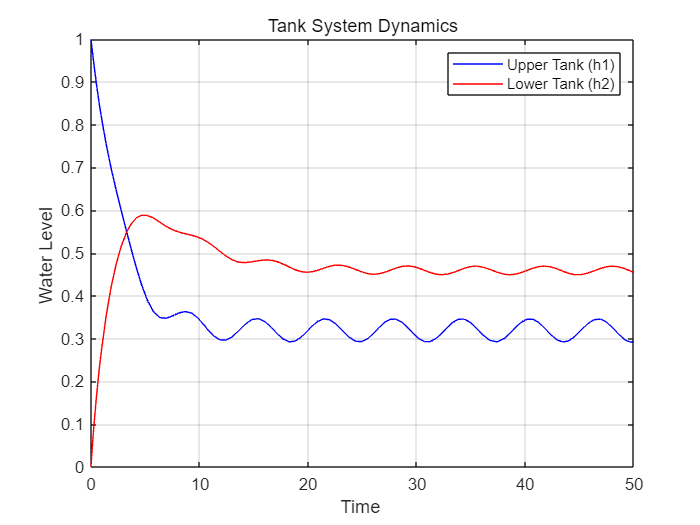

clear

% System parameters:
A1 = 1; % (m^2) Cross-sectional area of the upper tank 
A2 = 1.2; % (m^2) Cross-sectional area of the lower tank
a1 = 0.12; % (m^2) Area of the upper tank's orifice
a2 = 0.1; % (m^2) Area of the lower tank's orifice
K = 0.3; % (m^3/V*s) Pump constant
g = 9.8; % (m/s^2) Gravitational acceleration

% Initial conditions
h1_0 = 1; % (m) Initial water level in the upper tank
h2_0 = 0; % (m) Initial water level in the lower tank

V = @(t) 1 + 0.1*sin(t); % Input function (anonymous function)

%---------------------------------------------------------------
timespan = [0 50];


[t,h] = ode45(@(t,h) odefcn(t,h,A1,A2,a1,a2,K,g,V),timespan,[h1_0,h2_0]);

h1 = h(:,1);h2 = h(:,2);

figure;

plot(t, h1, 'b', t, h2, 'r');
xlabel('Time ');
ylabel('Water Level ');
legend('Upper Tank (h1)', 'Lower Tank (h2)');
title('Tank System Dynamics');
grid on;

%---------------------------------------------------------------


function dhdt = odefcn(t,h,A1,A2,a1,a2,K,g,V)
%---------------------------------------------------------------

%提取当前时间点的水位
h1 = h(1);
h2 = h(2);

dh1dt = (K / A1) * V(t) - (a1 * sqrt(2 * g * h1))/ A1;
dh2dt = (a1 * sqrt(2 * g * h1))/(A1*A2) - (a2 * sqrt(2 * g * h2))/ A2;
    
  
dhdt = [dh1dt; dh2dt];
%---------------------------------------------------------------
end

#### d)  Simulate the system using Simulink:

- **Use the same input and parameter values as specified in “2-c” above.**

- **Plot the system's response, i.e., the dynamics of **$h_1$** and **$h_2$**, for a duration of 50 seconds. ****Insert the plot below.**

- **Save your Simulink model with the filename “problem2Simulink.mdl”. **

# 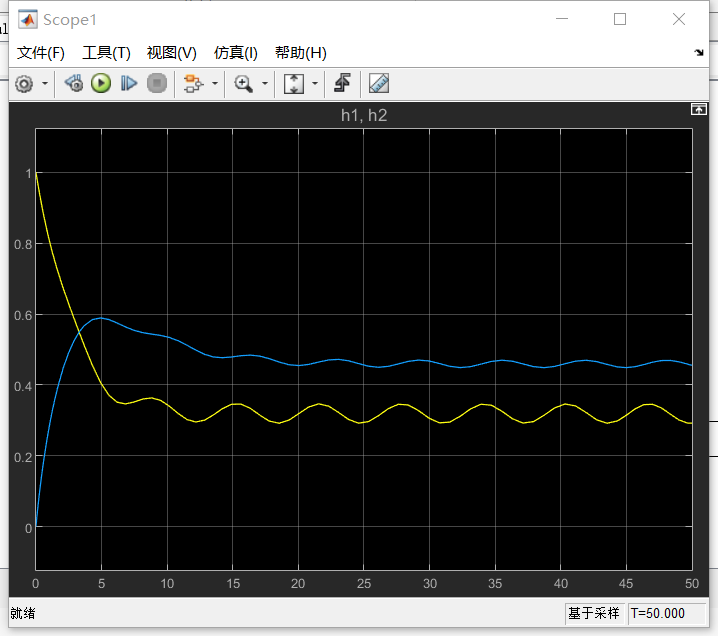

# **What to return?**

You are expected to submit your assignment to the related link for Assignment 2 in MyCourses.

Your submission should include:

- One completed .mlx file: “**Assignment_2_*your_student_number*.mlx**

- Two Simulink files:** problem1Simulink.mdl** and **problem2Simulink.mdl**